# Sinusoid Response

## Setup

clear all;
close all;
clc;

## Scelta della FDT

sys = zpk([0, 0], [-1, -1, -10, -10], 100)

sys =
 
      100 s^2
  ----------------
  (s+1)^2 (s+10)^2
 
Continuous-time zero/pole/gain model.
Model Properties


sys = tf(sys);

## Scelta della pulsazione della sinusoide e periodo associato

w = 0.1

w = 0.1000

f = w / 2 / pi

f = 0.0159

T = 1 / f

T = 62.8319

## Calcolo della risposta

### Funzioni custom

#### Variabili simboliche

syms u(t) U(s)
syms y(t) Y(s)

#### Ingresso

u(t) = 10*sin(w*t)

$$u(t) = 10\,\sin\left(\frac{t}{10}\right)$$

U(s) = laplace(u)

$$U(s) = \frac{1}{s^{2}+\frac{1}{100}}$$

#### Matrici dinamiche

[A,B,C,D] = tf2ss(sys.Numerator{1}, sys.Denominator{1})

A =    -22  -141  -220  -100
     1     0     0     0
     0     1     0     0
     0     0     1     0


B =      1
     0
     0
     0


C =      0   100     0     0


D = 0

eig(A)

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


#### Funzione di trasferimento

G(s) = transfer_function(A,B,C,D)

$$G(s) = \frac{100\,s^{2}}{s^{4}+22\,s^{3}+141\,s^{2}+220\,s+100}$$

#### Uscita

Y(s) = G(s) * U(s)

$$Y(s) = \frac{100\,s^{2}}{\left(s^{2}+\frac{1}{100}\right)\,\left(s^{4}+22\,s^{3}+141\,s^{2}+220\,s+100\right)}$$

y(t) = simplify(ilaplace(Y(s)));
disp(vpa(y, 2))

$$0.27\,{\mathrm{e}}^{-10.0\,t}-0.3\,{\mathrm{e}}^{-1.0\,t}+0.022\,\cos\left(0.1\,t\right)-0.097\,\sin\left(0.1\,t\right)+1.2\,t\,{\mathrm{e}}^{-1.0\,t}+1.2\,t\,{\mathrm{e}}^{-10.0\,t}$$

#### Grafico

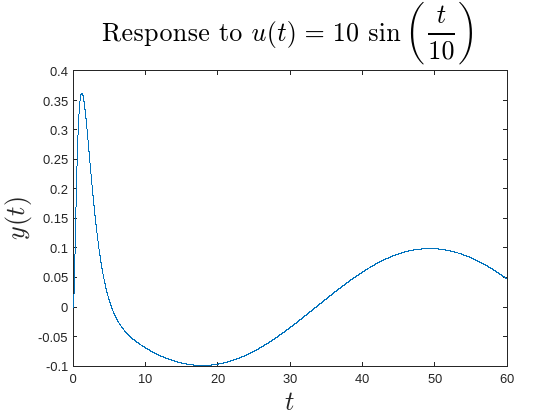

% Creare una nuova figura
figure(Name='Evoluzione forzata')

% Tempo limite per il grafico
TF = 60;
% Numero di campioni da graficare
NS = 10000;
% Intervallo di campionamento
TS = TF / NS;
% Definizione dell'asse temporale
tt = linspace(0, TF, NS);

% Grafico
plot(tt, y(tt));
xlim([tt(1) tt(end)])
xlabel('$$t$$', Interpreter='latex', FontSize=20)
ylabel('$$y(t)$$', Interpreter='latex', FontSize=20)
title(['Response to $$u(t)=' latex(u) '$$'],...
    Interpreter='latex', FontSize=20)

### Funzioni built-in di MATLAB

#### Definizione dell'ingresso

% u(t) = sin(0.1t)
[u, time] = gensig("sine", T, TF, TS);
% u(t) = 10sin(0.1t)
u = 10 * u;

#### Definizione dell'uscita

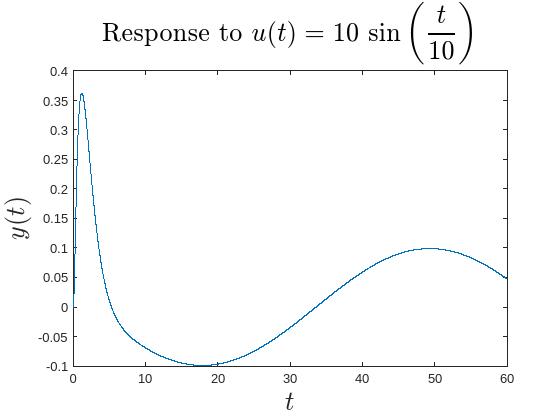

figure;
[y, time] = lsim(sys, u, time);
plot(time, y');
xlabel('$$t$$', Interpreter='latex', FontSize=20)
ylabel('$$y(t)$$', Interpreter='latex', FontSize=20)
title(['Response to $$u(t)=' latex(10 * sin(w*t)) '$$'],...
    Interpreter='latex', FontSize=20)

## Modifica del parametro w

w = 100

w = 100

f = w / 2 / pi

f = 15.9155

T = 1 / f

T = 0.0628

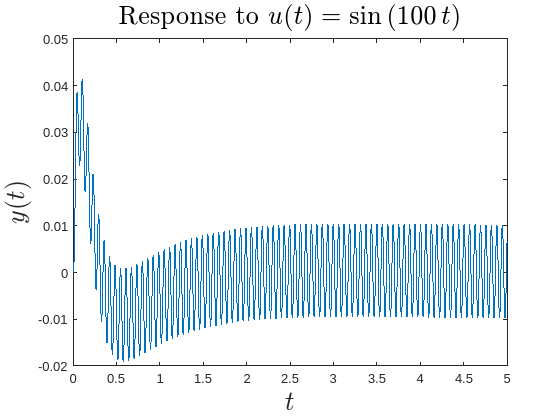

TF = 5;
TS = TF / NS;
[u, time] = gensig("sine", T, TF, TS);
figure;
[y, time] = lsim(sys, u, time);
plot(time, y');
xlabel('$$t$$', Interpreter='latex', FontSize=20)
ylabel('$$y(t)$$', Interpreter='latex', FontSize=20)
title(['Response to $$u(t)=' latex(sin(w*t)) '$$'],...
    Interpreter='latex', FontSize=20)

## Confronto tra più pulsazioni

### Scelta delle pulsazioni

ww = [0.1, 1, 5]

ww =     0.1000    1.0000    5.0000


### Grafico

#### **Parametri per lo stile del grafico**

% FontSize
FS = 15;
% LineWidth
LW = 1.75;

#### Parametri per la simulazione

% Tempo di Fine della simulazione
TF = 10; % [s]
% Tempo di campionamento (Sampling)
TS = TF / NS;

#### Grafico delle uscite

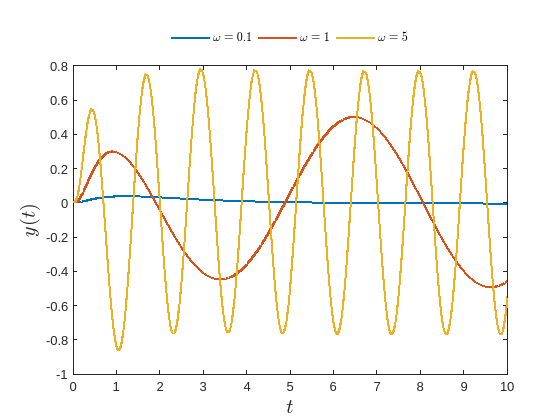

figure;
legend_names = string(size(ww));
for ii = 1 : length(ww)
    w = ww(ii);
    f = w / 2 / pi;
    T = 1 / f;
    [u, time] = gensig("sine", T, 10, TS);
    [y, time] = lsim(sys, u, time);
    plot(time, y'); hold on;
    xlabel('$$t$$', Interpreter='latex', FontSize=FS)
    ylabel('$$y(t)$$', Interpreter='latex', FontSize=FS)

    legend_names(ii) = ['$$\omega = ' num2str(w), '$$'];
    [~, lgd, ~, ~] = legend(legend_names(1:ii), Interpreter='latex',...
        Location='northoutside', Box='off', Orientation='horizontal');
end
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)
hold off;

#### Grafico degli ingressi

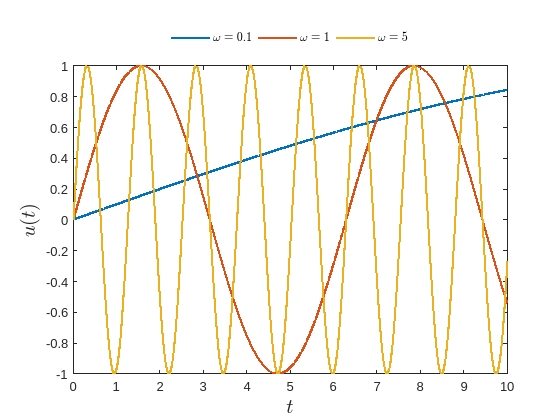

figure;
legend_names = string(size(ww));
for ii = 1 : length(ww)
    w = ww(ii);
    f = w / 2 / pi;
    T = 1 / f;
    [u, time] = gensig("sine", T, 10, TS);
    plot(time, u'); hold on;
    xlabel('$$t$$', Interpreter='latex', FontSize=FS)
    ylabel('$$u(t)$$', Interpreter='latex', FontSize=FS)

    legend_names(ii) = ['$$\omega = ' num2str(w), '$$'];
    [~, lgd, ~, ~] = legend(legend_names(1:ii), Interpreter='latex',...
        Location='northoutside', Box='off', Orientation='horizontal');
end
set(findall(gcf, Property='FontSize'), FontSize=FS)
set(findall(gcf, Type='Line'), LineWidth=LW)
set(findobj(lgd, Type='Line'), LineWidth=LW)
hold off;

## Risposta all'onda quadra

L'onda quadra può essere vista come una somma periodica di gradini di ampiezza uguale ed opposta

### Definizione dell'ingresso

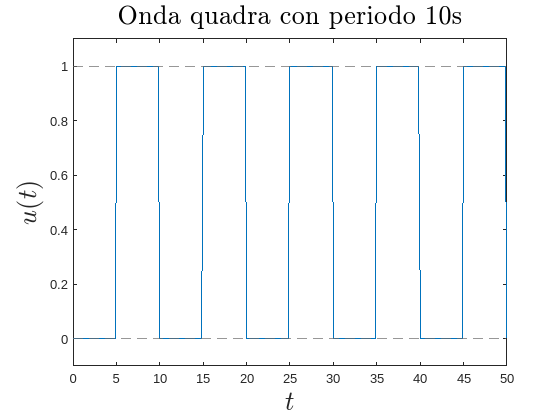

% Periodo
T = 10;
% Segnale
[u, time] = gensig("square", T);
% Grafico
figure;
plot(time, u)
xlabel('$$t$$', Interpreter='latex', FontSize=20)
ylabel('$$u(t)$$', Interpreter='latex', FontSize=20)
title(['Onda quadra con periodo ' num2str(T) 's'],...
    Interpreter='latex', FontSize=20)
ylim([-0.1, 1.1])
yline(0, '--', LineWidth=0.42, Color=[0.42 0.42 0.42])
yline(1, '--', LineWidth=0.42, Color=[0.42 0.42 0.42])

### Definizione del sistema

sys2 = tf(30, [1 5 30])

sys2 =
 
        30
  --------------
  s^2 + 5 s + 30
 
Continuous-time transfer function.
Model Properties


#### Definizione dell'uscita

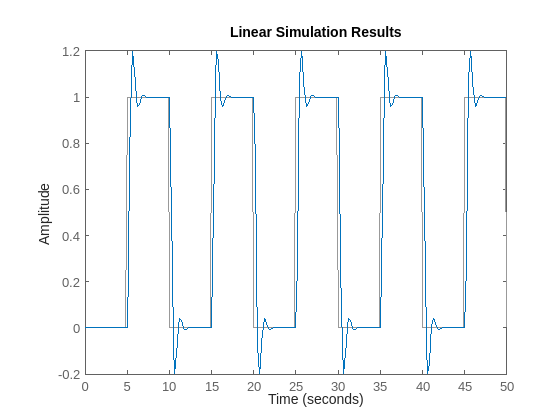

lsim(sys2, u, time)
set(findall(gcf, Property='FontSize'), FontSize=12)
set(findall(gcf, Type='Line'), LineWidth=1.25)